# Example with symbolic values

This example shows how to use the symbolic beam solver with a task on hand.

*Task:*

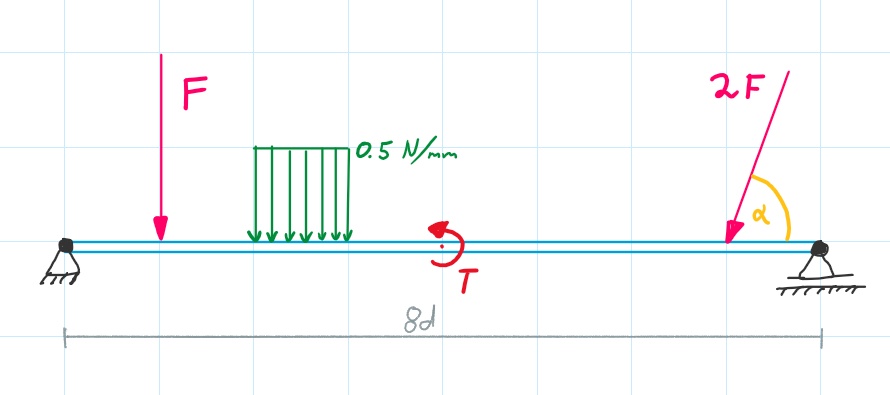

clear 'all'  % clear all variables ('all' also clears assumptions)

syms d F T alpha  % define symbolic variables

#### create a beam

mybeam = beam(8*d);  % define a beam with given length

#### define external influences

% Bearings
Bearing_A = bearing(0, 2, 'A');
Bearing_B = bearing(8*d, 1, 'B');

% Pointloads/Forces
F1 = pointload(d, F);
F2 = pointload(7*d, 2*F, alpha);

% Lineload
L1 = lineload(2*d, 3*d, 0.5);

% Torque
T1 = torque(4*d, T);

#### add influeces to beam

mybeam.bearings = [Bearing_A, Bearing_B];
mybeam.pointloads = [F1, F2];
mybeam.torques = T1;
mybeam.lineloads = L1;

#### give numerical values to symbols

This is only for visualizing and does not affect the solution. It is strongy reccommended if you use symbolic variables

mybeam.symVars =    [d F T alpha];
mybeam.numReplace = [100, 50, 5000, 70];

#### check beam-setup

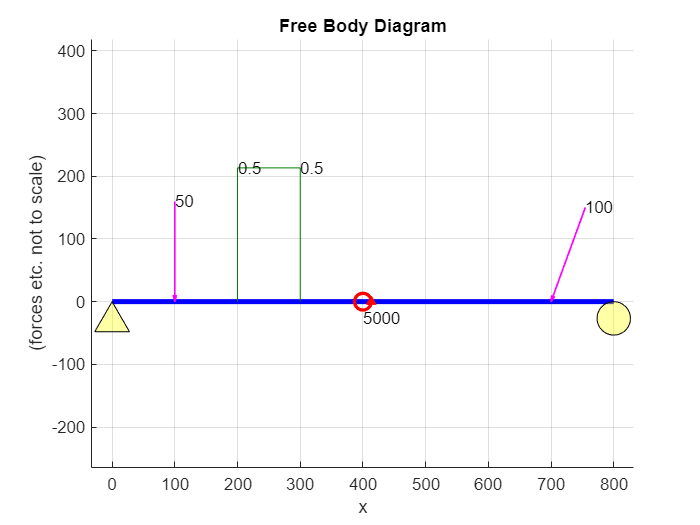

figure(1); clf; hold on; grid on; axis equal;
mybeam.plot_beam()

#### solve beam

Especially when using symbolic variables this process may take a while

mybeam.fullsolve()  % this solves the beam

#### visualize shear forces and bending moment

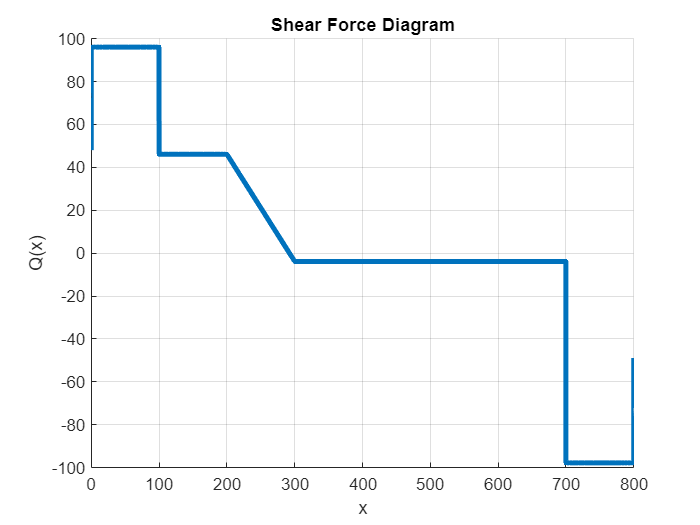

figure(2); clf; hold on; grid on;
mybeam.plot_Q()

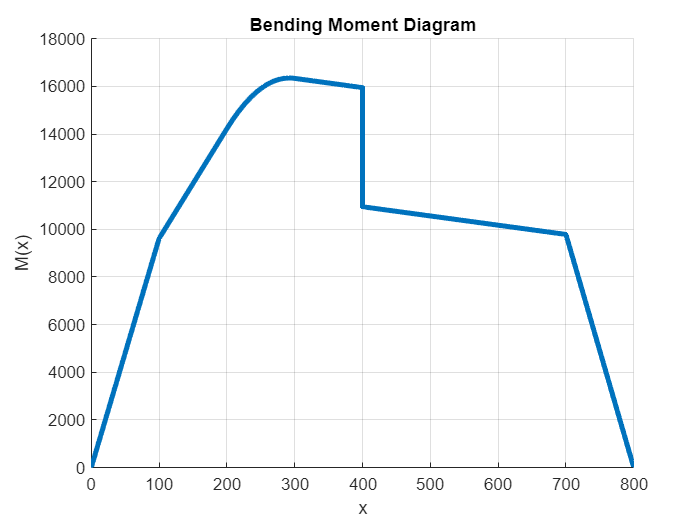


figure(3); clf; hold on; grid on;
mybeam.plot_M()

#### show formula for shear forces and bending moment

myQ = mybeam.Q

$$myQ = \begin{array}{l} d\,\sigma_{3}-F\,\mathrm{heaviside}\left(x-d\right)-\frac{x\,\left(\sigma_{3}-\sigma_{2}\right)}{2}-\frac{3\,d\,\sigma_{2}}{2}-2\,F\,\mathrm{heaviside}\left(x-7\,d\right)\,\sigma_{1}+\frac{\mathrm{heaviside}\left(x\right)\,\left(4\,T+28\,F\,d+11\,d^{2}+8\,F\,d\,\sigma_{1}\right)}{32\,d}+\frac{\mathrm{heaviside}\left(x-8\,d\right)\,\left(4\,F\,d-4\,T+5\,d^{2}+56\,F\,d\,\sigma_{1}\right)}{32\,d}\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\frac{\pi \,\alpha }{180}\right)\\ \sigma_{2}=\mathrm{heaviside}\left(x-3\,d\right)\\ \sigma_{3}=\mathrm{heaviside}\left(x-2\,d\right) \end{array}$$

myM = mybeam.M

$$myM = \begin{array}{l} \frac{9\,d^{2}\,\sigma_{1}}{4}-d^{2}\,\sigma_{2}-\sigma_{3}\,\sigma_{5}-\frac{x^{2}\,\sigma_{2}}{4}+\frac{x^{2}\,\sigma_{1}}{4}-\frac{5\,d^{2}\,\mathrm{heaviside}\left(-d\right)}{4}+\mathrm{heaviside}\left(-d\right)\,\sigma_{5}-T\,\mathrm{heaviside}\left(x-4\,d\right)+T\,\mathrm{heaviside}\left(-d\right)+F\,d\,\mathrm{heaviside}\left(x-d\right)-F\,x\,\mathrm{heaviside}\left(x-d\right)-F\,d\,\mathrm{heaviside}\left(-d\right)+d\,x\,\sigma_{2}-\frac{3\,d\,x\,\sigma_{1}}{2}+\frac{x\,\mathrm{heaviside}\left(x\right)\,\left(4\,T+28\,F\,d+11\,d^{2}+8\,F\,d\,\sigma_{6}\right)}{32\,d}+\frac{x\,\sigma_{3}\,\left(4\,F\,d-4\,T+5\,d^{2}+56\,F\,d\,\sigma_{6}\right)}{32\,d}+14\,F\,d\,\sigma_{4}\,\sigma_{6}-2\,F\,x\,\sigma_{4}\,\sigma_{6}-14\,F\,d\,\mathrm{heaviside}\left(-d\right)\,\sigma_{6}\\ \mathrm{where}\\ \sigma_{1}=\mathrm{heaviside}\left(x-3\,d\right)\\ \sigma_{2}=\mathrm{heaviside}\left(x-2\,d\right)\\ \sigma_{3}=\mathrm{heaviside}\left(x-8\,d\right)\\ \sigma_{4}=\mathrm{heaviside}\left(x-7\,d\right)\\ \sigma_{5}=F\,d-T+\frac{5\,d^{2}}{4}+14\,F\,d\,\sigma_{6}\\ \sigma_{6}=\sin\left(\frac{\pi \,\alpha }{180}\right) \end{array}$$

#### **Now you can do whatever you please**

The following example shows how to get the bending moment on the position 5*d on the beam:

syms x  % define x
M_5d = subs(myM, x, 5*d)  % insert 5*d as x

$$M\_5d = \begin{array}{l} \frac{5\,\mathrm{heaviside}\left(-d\right)\,\left(4\,F\,d-4\,T+5\,d^{2}+56\,F\,d\,\sigma_{1}\right)}{32}-\frac{5\,d^{2}\,\mathrm{heaviside}\left(-d\right)}{4}-T\,\mathrm{heaviside}\left(d\right)+T\,\mathrm{heaviside}\left(-d\right)-\frac{5\,d^{2}\,\mathrm{heaviside}\left(d\right)}{4}+\frac{5\,\mathrm{heaviside}\left(d\right)\,\left(4\,T+28\,F\,d+11\,d^{2}+8\,F\,d\,\sigma_{1}\right)}{32}-F\,d\,\mathrm{heaviside}\left(-d\right)-4\,F\,d\,\mathrm{heaviside}\left(d\right)-10\,F\,d\,\mathrm{heaviside}\left(-d\right)\,\sigma_{1}\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\frac{\pi \,\alpha }{180}\right) \end{array}$$

This yields a pretty big result with the heaviside function inside the term. This can be simplified a bit more though.

In our case it's clear that d will always be greater than 0 to make sense of the problem. You can tell MATLAB this with the [assume()](https://de.mathworks.com/help/symbolic/sym.assume.html) or the [assumeAlso()](https://de.mathworks.com/help/symbolic/sym.assumealso.html) function. Check the example_assume.mlx for more info.

assumeAlso(d > 0)
M_5d_new = simplify(M_5d)

$$M\_5d\_new = \frac{3\,F\,d}{8}-\frac{3\,T}{8}+\frac{15\,d^{2}}{32}+\frac{5\,F\,d\,\sin\left(\frac{\pi \,\alpha }{180}\right)}{4}$$

Now we have a much more managable result!